# Synthesis of the connection of three pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_1');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_1



Parameters

p0 = 600

mu = 9.9792e-04

D_coeff = 4.9000e-10


% Load a video file for image processing
videoFileName = fullfile(pwd, 'CNN_Inlet_500_ms (1).mp4');
videoFileName = fullfile(pwd, 'CNN_Inlet_1_s (1).mp4');
videoFileName = fullfile(pwd, 'CNN_Inlet_1_5_s (1).mp4');
videoObject = VideoReader(videoFileName);

% Check if the video file exists
if ~isfile(videoFileName)
    error('Video file does not exist. Please check the file name and path.');
end

% Get video properties
frameRate = videoObject.FrameRate
totalFrames = floor(videoObject.Duration * frameRate);

fprintf('Total number of frames: %d\n', totalFrames);

Total number of frames: 36



% Define start and end time (in seconds)
startTime = 5;  % e.g., start at 4 seconds
endTime   = 15; % e.g., end at 10 seconds

% Set the video reader to the start time
videoObject.CurrentTime = startTime;

% Initialize cell array to store frames
segmentedFrames = {}; 
frameIdx = 1;

% Read frames between startTime and endTime
while hasFrame(videoObject) && videoObject.CurrentTime <= endTime
    frame = readFrame(videoObject);
    segmentedFrames{frameIdx} = frame;  %#ok<SAGROW> store current frame
    frameIdx = frameIdx + 1;
end

fprintf('Stored %d frames between %.2f s and %.2f s\n', numel(segmentedFrames), startTime, endTime);

Stored 21 frames between 5.00 s and 15.00 s




% Create a VideoWriter object to save the processed frames
outputVideoFileName = fullfile(pwd, ['Processed_' videoObject.Name]); % Prepend "processed_" to the original video name
outputVideo = VideoWriter(outputVideoFileName, 'MPEG-4'); % Specify the video format
outputVideo.FrameRate = videoObject.FrameRate; % Set the frame rate
open(outputVideo); % Open the video file for writing

% Write the segmented frames to the video file
for j = 1:length(segmentedFrames)
    writeVideo(outputVideo, uint8(segmentedFrames{j})); % Convert to uint8 and write the frame
end

close(outputVideo); % Close the video file
fprintf('Processed video saved as: %s\n', outputVideoFileName);

Processed video saved as: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_1\experimental work\videos_pics_Design_1_1_microfluidic_pipes_9_Oct_2025\Processed_CNN_Inlet_1_5_s (1).mp4


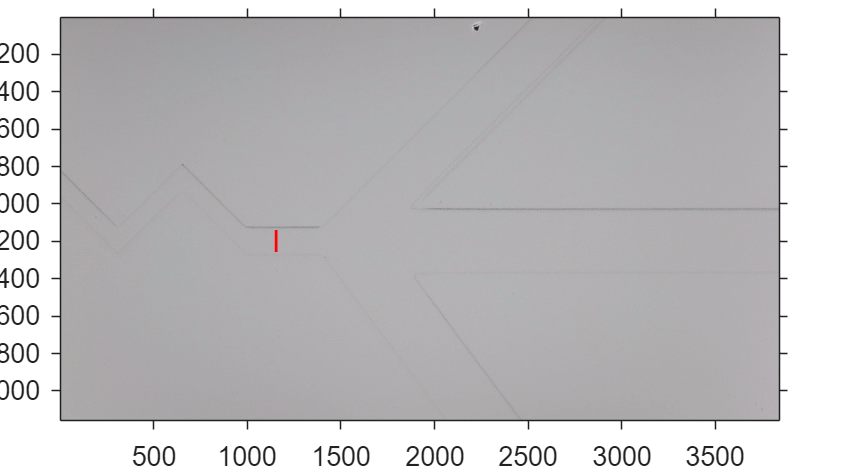

% Predefined coordinates for the line for 500ms pulse
xCoords = [1388, 1388]; % X coordinates
yCoords = [1078, 1248]; % Y coordinates

% Predefined coordinates for the line for 1s pulse
xCoords = [1632, 1632]; % X coordinates
yCoords = [1203, 1033]; % Y coordinates

% Predefined coordinates for the line for 1s pulse
xCoords = [1154, 1154]; % X coordinates
yCoords = [1139, 1257]; % Y coordinates

% Plot the first frame of segmentedFrames with axes
if ~isempty(segmentedFrames)
    figure; % Create a new figure window
    imshow(segmentedFrames{1}); % Display the first frame
    axis on; % Turn on the axes
    xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
    ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis    
    
    % Hold the current plot to overlay the line
    hold on;
    plot(xCoords, yCoords, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    hold off;
    set(gca,"FontSize",fontsize)
else
    warning('No frames available to display.');
end


% Initialize an array to store the average intensity values
averageIntensities = zeros(1, length(segmentedFrames));

% Loop through each frame to calculate the average intensity along the line
for k = 1:length(segmentedFrames)
    frame = segmentedFrames{k};
    
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile = improfile(frame, xCoords, yCoords);
    
    % Calculate the average intensity for the pixels along the line
    averageIntensities(k) = mean(lineProfile(:));
end


%Swapping the values of averageIntensities around its maximum 
max_averageIntensities=max(averageIntensities);
min_averageIntensities=min(averageIntensities);

averageIntensities_swap=-(averageIntensities-max_averageIntensities);

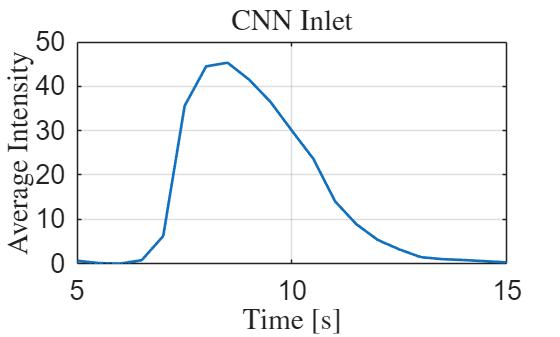

% Plot average intensities over time
timeVector = linspace(startTime, endTime, length(averageIntensities_swap)); % Create a time vector
figure; % Create a new figure window
plot(timeVector, averageIntensities_swap, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Average Intensity', 'Interpreter', 'latex'); % Label for Y-axis
title('CNN Inlet', 'Interpreter', 'latex'); % Title of the plot
grid on; % Turn on the grid
set(gca, 'FontSize', fontsize); % Set font size for axes

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end

function trow = makeRow(var, description, unit, scale)
    name = inputname(1);
    valStr = sprintf('%g[%s]', var*scale, unit);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end

function trow = makeRow_no_unit(var, description)
    name = inputname(1);
    valStr = sprintf('%g', var);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end